## Get training images

%This line of code gets the flower images from the folder where thay'er
%stored and names them according to the name of the sub-folder where
%they're stored.
imds = imageDatastore('Flowers','IncludeSubfolders',true,'LabelSource','foldernames');

Split into training and testing sets

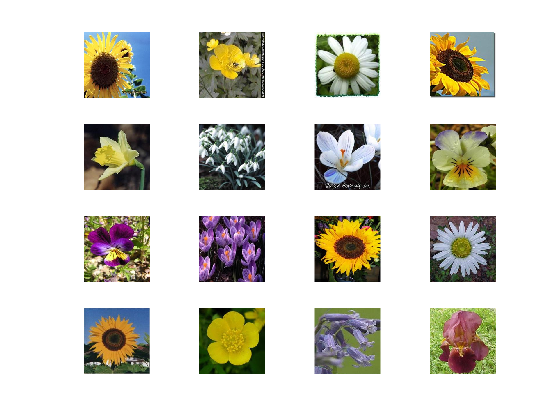

%This block of code splits the images in a ratio of 6:4 or 60:40%
%where 60% of the images is for training while the remaining 40% is for
%testing.
%Note: the 60% is randomised while the 40% are correctly labeled.
%And some of the images are displayed on the right side of the IDE
%randomly.
%The for loop displays images 1 to 16
[imdsTrain,imdsTest] = splitEachLabel(imds,0.6,'randomized');
numTrainImages = numel(imdsTrain.Labels);
idx = randperm(numTrainImages,16);
figure
for i = 1:16
    subplot(4,4,i)
    I = readimage(imdsTrain,idx(i));
    imshow(I)
end

Determine the number of flower species

%This line of Code determines how many different sepcies of floweres are in
%the folder by counting the number of sub-folders, fetching and assigning
%their names to the numClasses variable
numClasses = numel(categories(imds.Labels));

## Create a network by modifying Renet18

Get the layers from Resnet18

%In this Section we're using the Resnet18 network for the training so we
%assign the Resnet18 network to the variable net
%In this Section we get the layers of the Resnet18 network, which we'll
%modify to input and output layers to suit our need
net = resnet18

net =   DAGNetwork with properties:

         Layers: [71×1 nnet.cnn.layer.Layer]
    Connections: [78×2 table]
     InputNames: {'data'}
    OutputNames: {'ClassificationLayer_predictions'}


Modify the classification and output layers

%In this Section we get the layers of the Resnet18 network, which we'll
%modify to input and output layers to suit our need.
inputSize = net.Layers(1).InputSize;
analyzeNetwork(net)
augimdsTrain = augmentedImageDatastore(inputSize(1:2),imdsTrain);
augimdsTest = augmentedImageDatastore(inputSize(1:2),imdsTest);
layer = 'pool5';
featuresTrain = activations(net,augimdsTrain,layer,'OutputAs','rows');
featuresTest = activations(net,augimdsTest,layer,'OutputAs','rows');

%This line of code list the contents or result of featuresTrain
whos featuresTrain

## Set training algorithm options

Lower the learning rate for transfer learning

%In this section i'm assigning the labels of the trained images and test
%images to the variables Ytrain and Ytest respectively
YTrain = imdsTrain.Labels;
YTest = imdsTest.Labels;

## Perform training

%In this line of code we're training the Ytrain labels set aside for
%training using the "fitcecoc" model of the SVM and assigning the result to
%the variable 
classifier = fitcecoc(featuresTrain,YTrain);

## Use the trained network to classify test images

%This line of code uses the trained network to test the images set aside
%for testing "featuresTest".
YPred = predict(classifier,featuresTest);

## Evaluate the results

%This block of code displays some of the images with their
%predicted labels.
idx = [1 5 7 10 15 20,];
figure
for i = 1:numel(idx)
    subplot(3,3,i)
    I = readimage(imdsTest,idx(i));
    label = YPred(idx(i));
    imshow(I)
    title(char(label))
end

Visualize the confusion matrix

%This line of code calculates the accuracy of the prediction
accuracy = mean(YPred == YTest)

%This line of code calculates the confusionchart
confusionchart(imdsTest.Labels,YPred);

%This line of code plots the confusionchart diagram
plotconfusion(imdsTest.Labels,YPred)

%This line of code assigns the result of the confusion matrix to the
%varaible confMat, so its can be used in other calculations.
confMat = confusionmat(testImgs.Labels, testpreds);

%This line of code transpose's the confMant
confMat = confMat';

%This block of code calculates the precision of the results, by determining
%the precision first then the overrall precision, which is the average
%prcision of the whole system.
precision = diag(confMat)./sum(confMat,2);
overall_precision = mean(precision)

%This block of code calculates the recall of the results, by determining
%the recall first then the overrall recall, which is the average
%recall of the whole system.
recall= diag(confMat)./sum(confMat,1)';
overall_recall = mean(recall)
